# **C222: Live cell analysis**

**Variables:**

crlNuc = mean CRL4Cdt2 reporter intensity within nucleus

POI(:,3) = time of CRL4Cdt2 activation

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'DMSO',2:7,2,1:9,[0 0 0]; %1      
        'DOX',2:7,3:11,1:9,[0 0 0]; %1    
    };

load([dataDir filesep 'C222_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 3.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



Median CRL traces aligned to CRL4 deg start

conds=[1 2];
POI_align = 3;
f1 = figure('Units', 'Inches', 'Position', [0, 0, 4*(length(conds)+1), 4]);

rng(4)
colors = lines(length(conds));
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) ...
        & max(data.crlNuc,[],2) > 500 & max(data.crlNuc,[],2) < 1000 ;
    if any(c == [2 3])
        inds = inds & data.YFP1 > 2^10;
    end
    sum(inds)
    [frames, medSig, semCRL] =get_mean_trace((data.crlNormAct(inds,:)),data.POI(inds,POI_align),1);
    
    subplot(1,length(conds)+1,length(conds)+1)
    hold on
    errorbar((frames)/framesPerHr,medSig,semCRL,'LineWidth',1.5);
    
    subplot(1,length(conds)+1,i)
    hold on
    cells = find(inds);
    for numcell = randsample(cells,min([50 length(cells)]))'
        timeAligned = xFrames-data.POI(numcell,POI_align);
        patchline(timeAligned/framesPerHr,nansmoothm(data.crlNormAct(numcell,:),5,'sgolay'),...
            'edgecolor',colors(i,:),'linewidth',1,'edgealpha',0.2);
        
    end
    xlim([-.5 1.5]);
    xticks([-.5:.5:1.5])
    ylim([0 1.2]);
    ylabel('Normalized CRL4 sensor');
    xlabel('Time since CRL4 deg start (hrs)');
    axis square
end

ans = 484

ans = 2629

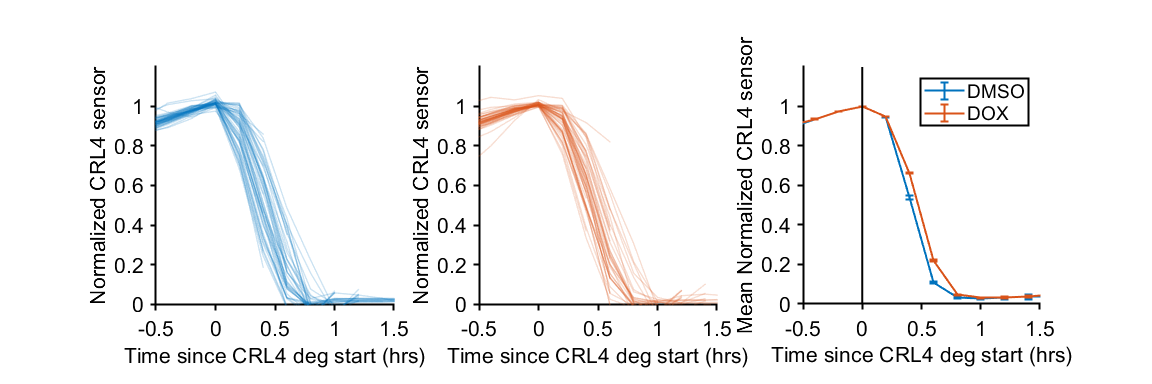


subplot(1,length(conds)+1,length(conds)+1)
    xlim([-.5 1.5]);
    xticks([-.5:.5:1.5])
ylim([0 1.2]);
axis square
vline(0,'k')
    ylabel('Mean Normalized CRL4 sensor');
    xlabel('Time since CRL4 deg start (hrs)');
legend(conditions(conds,1));

print_pdf([pwd() '\Figs\CRLdeg.pdf'])

**comparing CRL4 activation times**

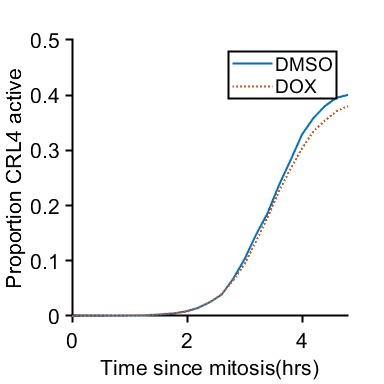

conds=[1 2];
offset=0;

% f = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
% hold on
f2 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
hold on
gateddata = {};
% cols = lines(2);
% cols = [0 113 188; 193 39 45]/255;
cols = lines(3);
% cols = [cols(1,:); cols(3,:); cols(2,:); cols(4,:)];
style = {'-',':',':'};
for i=1:length(conds)
    
    if any(conds(i)==[1])
        inds = true(size(S(conds(i)).area(:,end)));
    else
        inds = S(conds(i)).YFP1 > 2^11;
        
    end
    
    data = (S(conds(i)).POI(inds,3) - S(conds(i)).POI(inds,1))/framesPerHr;
    data_end = (numFrames - S(conds(i)).POI(inds,1))/framesPerHr;
    figure(f2)
    hold on
    data_filt = data;
    data_filt(isnan(data_filt)) = (numFrames - S(conds(i)).POI(isnan(data_filt),1))/framesPerHr;
    [prob, x] = ecdf(data_filt,'function','cdf','censoring',isnan(data),'bound','off');
%     patchline(x,prob,'EdgeAlpha',.5,'LineWidth',2,'EdgeColor',cols(i,:));
    plot(x,prob,style{i},'Color',cols(i,:))
%     xlim([8 18])
    xlabel('Time since mitosis(hrs)')
    ylabel('Proportion CRL4 active')
    axis square
    gateddata{i} = data(~isnan(data));    
    cells = length(data);
end
legend(conditions(conds,1))

% figure(f)
% nhist(gateddata,'npoints','pdf','sem','samebins','fsize',16,'legend',conditions(conds,1));
% %     xlim([4 10])
% %     ylim([5 12])
% xlabel('CRL4 activation (hrs)')

print_pdf([pwd() '\Figs\CRLtimescumul.pdf'])